# COTS Live Script 5

I will probably upload this livescript to github as its purpose is to run through the process of taking COTS trajectory data and converting it to a connectivity matrix

## Load Data

if ~exist("workspaceVar")
    load matlabCOTS.mat
end

## Save Data

if workspaceVar
    clear ans test test1 test2 test3 r c l i
    save matlabCOTS.mat
end

## Contents

Loading data - loads in the particle tracking results, 

Processing data - taking some of the raw data provided and converting into more useful forms

Setup searching algorithm - setting up the searching algorithm which is used to determine if a point lies within a reef

Assign initial reefs - use the searching algorithm to assign the reefs at which each larvae begins at

Enlarge reefs - according to Mike, for the settlement processes we allow a COTS larvae to settle at a reef if it is within 1km distance from it - hence I wrote some code to enlarged each reef by 1km

Prepare death and settlement processes - need to alter some of the raw data on death and settlement to assure it is reasonable

Assign final reefs and create connectivity matrix - use everything from the previous steps to determine the reefs at which COTS settle at, and henceforth create a connectivity matrixz

## Loading in data

% I will add a .mat file in the github which will contain all the data and
% results, which can be loaded at the top of this page - otherwise, you can
% load in the individual data from the remaining code in this section,
% however clearly you will need to change the file paths

% load in the particle tracking data - clearly if others are using this
% they will need to change the filepath
resultsFile = readtable("C:\Users\sowen\Documents\Research Assistant Work\COTS\Data\Results\GBR_20181201_COTS_1day");

% also here load in the correct shapefile - Sev's data records positions in
% UTM so we are going to load in a shapefile in UTM Coords
GBRShape = shaperead("C:\Users\sowen\Documents\Research Assistant Work\COTS\Data\Sevs gbr files\Marine_Bioregions_of_the_Great_Barrier_Reef__Reef_UTM55S.shp");

% I gained death and settlement processes using Engauge digitiser from some
% paper on COTS larvae Mike sent me, so need to load in and process the
% data to ensure accuracy
% for now I will just load in the medium food option, however low and high
% food curves are also available
midFSettProp = readmatrix("C:\Users\sowen\Documents\Research Assistant Work\COTS\Data\Digitised Functions\IntermediateFoodSettlement_days_prop.csv");
midFSurvCount = readmatrix("C:\Users\sowen\Documents\Research Assistant Work\COTS\Data\Digitised Functions\IntermediateFoodSurvivorship_days_count.csv");

## Processing data

% the resultsFile consists of a table of 14 million rows, each of which
% represents a different position of a COTS larvae - we are going to
% convert this into a structure instead, where each element is a separate
% larvae, and holds its seed, release time, release position and all x, y
% and time data
% we first need to extract all the unique seeds, and set up the table
% headings
% set the table headings
resultsFile.Properties.VariableNames = ["seed","initialX","initialY","releaseTime_seconds", "reefIndex", "time_days", "xPos", "yPos"];

% before creating the COTS struct, we need to extract all the unique seeds
uniqueSeeds = unique(resultsFile{:, "seed"});
nCOTS = length(uniqueSeeds);

% create the seeds array, which will convert a seed back to an index of the
% seeds in ascending order, as the seeds themselves have some gaps e.g.
% first seed is 10 not one
seeds = zeros(max(uniqueSeeds), 1);
for s = 1:length(uniqueSeeds)
    seeds(uniqueSeeds(s)) = s;
end

% for demonstration, seeds(10) should be 1 as the first seed is 10
seeds(10)

ans = 1

% now we can create the COTS struct
COTSStruct = createCOTSStruct(resultsFile, seeds, uniqueSeeds);

% now clear the results file so we aren't taking up memory unnecessarily
clear resultsFile

ans =         17868


ans =        3.3333


ans =         17867


ans =        17870


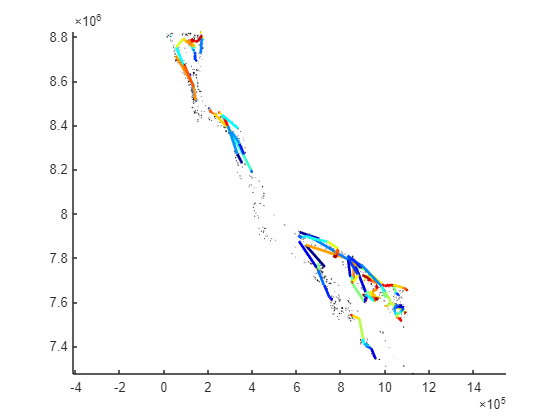

% just to examine the data, plot the paths of some of the COTS larvae
plotCOTSPath(GBRShape, COTSStruct, 1:1000:34000)

## Setup searching algorithm

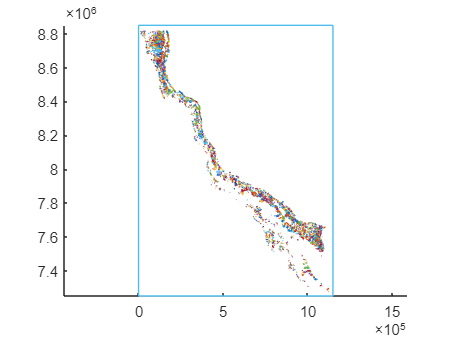

% to determine the initial and final positions of each larvae, I wrote a
% searching algorithm that will significantly speed up the time taken to
% determine whether or not a larvae is above a reef, using a grid - like
% structure over the reef which is searched first, before looking into
% individual reefs
% we will create a 120 x 120 grid, any higher resolution does not appear to
% produce any more gains in speedup
% to do so, we need to specify a border over the search space, which will
% be done below and plotted 
border = [0, 7.25*10^6; 11.5*10^5, 7.25*10^6; 11.5*10^5, 8.85*10^6; 0, 8.85*10^6; 0, 7.25*10^6];
plotGBRShape(GBRShape, "fig", "holdOn")
plot(border(:, 1), border(:, 2))

% this code creates the overall grid
partArr120 = gridPartRectangle(border, [120, 120]);

% before we do the next step, we need to add a Centroid field to GBRShape
GBRShape = calcCentroids(GBRShape);

% this code removes any grid cells which do not contain any reefs, and are
% hence unnecessary
[partArr120, partCell120] = removeCells(GBRShape, partArr120, [120, 120]);

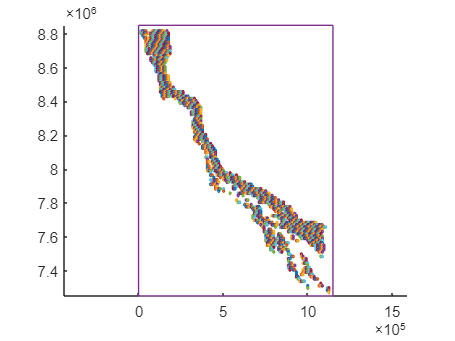

% visualise the grid
plotGBRShape(GBRShape, "fig", "holdOn")
plotGrid(partArr120, "", "holdOn")
plot(border(:, 1), border(:, 2))

% we now need to set up what I call a searchCell, which is used in the
% searching algorithm
searchCell120 = createSearchCell(partArr120, partCell120, [border(1, 1), border(2, 1)], [border(1, 2), border(3, 2)], 120, 120);

% ensure the method is working by checking which centroids are inside their
% reef
nReefs = length(GBRShape);
test = zeros(nReefs, 1);
for r = 1:nReefs
    test(r) = findReefFast(GBRShape(r).Centroid, GBRShape, searchCell120);
end

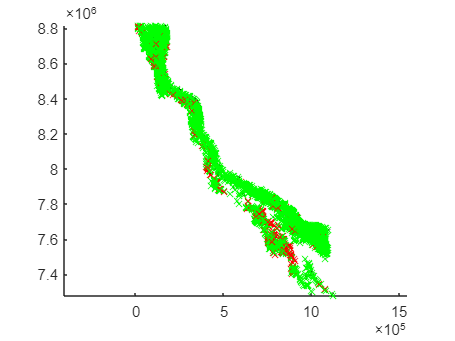

% plot the results to ensure all centroids which are inside the reef
% outlines are correctly identified
plotGBRShape(GBRShape, "fig", "holdOn", "no", "k")
for r = 1:nReefs
    if test(r) > 0
        plot(GBRShape(r).Centroid(1), GBRShape(r).Centroid(2), 'gx')
    else
        plot(GBRShape(r).Centroid(1), GBRShape(r).Centroid(2), 'rx')
    end
end

## Assign initial reefs

% now that the searching algorithm has been set up, let's assign the
% initial reefs
initialReefs = assignInitialReefs(COTSStruct, GBRShape, searchCell120, partArr120);

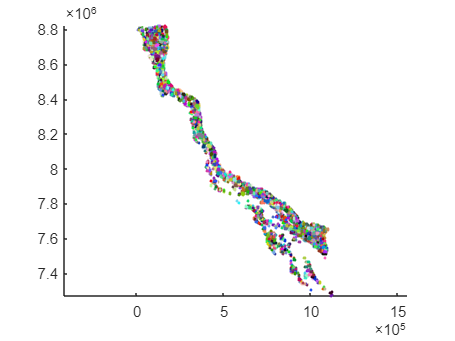

% plot the results which can be checked by visual inspection (enlarge the
% figure and zoom in - reefs and the points assigned to them should all be
% the same colour)
initialPos = zeros(nCOTS, 2);
for c = 1:nCOTS
    initialPos(c, :) = [COTSStruct(c).initialX, COTSStruct(c).initialY];
end
plotAssignments(GBRShape, initialPos, initialReefs);

## Enlarge reefs

% when examining the settlement of the reefs, Mike has said to enlarge all
% the reefs by 1km, and if a larvae is able to settle and in this 1km
% radius of a reef, it will settle there - hence we need to enlarge the
% reefs, and then setup some parameters of the searching algorithm again to
% accomodate for the now enlarged reefs
GBRShapeEnlarged = enlargeShapes(GBRShape, 1000);

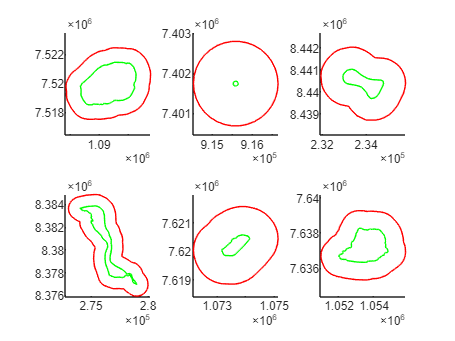

% ensure the reefs have been enlarged correctly by plotting some of the
% reefs original and enlarged versions on top of each other
rVec = [28, 56, 2003, 2002, 560, 670];
figure
for r = 1:length(rVec)
    subplot(2, 3, r)
    hold on
    plot(GBRShape(rVec(r)).X, GBRShape(rVec(r)).Y, 'g')
    plot(GBRShapeEnlarged(rVec(r)).X, GBRShapeEnlarged(rVec(r)).Y, 'r')
    axis equal
end

% update the searching algorithm for the enlarged reefs, starting from an
% original grid in case the 1km enlargement means that reefs will cross
% over to space without a grid cell
partArr120OG = gridPartRectangle(border, [120, 120]);
[partArr120Enlarged, partCell120Enlarged] = removeCells(GBRShapeEnlarged, partArr120OG, [120, 120]);

% now create the new search cell
searchCellEnlarged = createSearchCell(partArr120Enlarged, partCell120Enlarged, [border(1, 1), border(2, 1)], [border(1, 2), border(3, 2)], 120, 120);

% as before, ensure the method is working by checking which centroids are
% inside their reef
test = zeros(nReefs, 1);
for r = 1:nReefs
    test(r) = findReefFast(GBRShape(r).Centroid, GBRShapeEnlarged, searchCellEnlarged);
end

ans = 2960

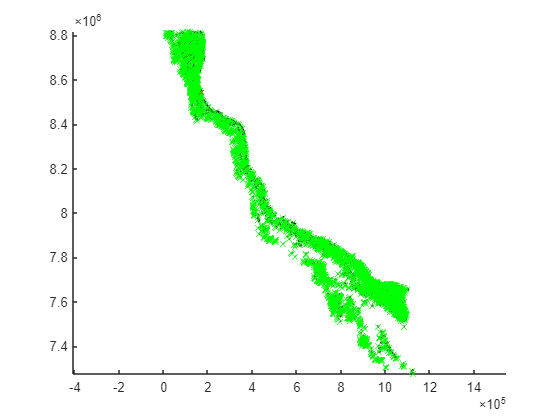

% plot the results to ensure all centroids which are inside the reef
% outlines are correctly identified
plotGBRShape(GBRShapeEnlarged, "fig", "holdOn", "no", "k")
for r = 1:nReefs
    if test(r) > 0
        plot(GBRShape(r).Centroid(1), GBRShape(r).Centroid(2), 'gx')
    else
        plot(GBRShape(r).Centroid(1), GBRShape(r).Centroid(2), 'rx')
    end
end

## Prepare death and settlement processes

% transpose them all quickly
midFSettProp = midFSettProp';
midFSurvCount = midFSurvCount';

% alright need to quickly interpolate the functions so we can get a day
% by day analysis
interval = 1;
midFSett = interpolateFunction(midFSettProp, interval);
midFSurv = interpolateFunction(midFSurvCount, interval);

% going to set any negatives to zeros
test = midFSurv(2, :) < 0;
midFSurv(2, test) = 0;
test = midFSett(2, :) < 0;
midFSett(2, test) = 0;

% now I'm going to make sure that the survivorship counts are monotically
% decreasing
for i = 2:length(midFSurv)
    if midFSurv(2, i-1) <= midFSurv(2, i)
        midFSurv(2, i) = 0.95 * midFSurv(2, i-1);
    end
end

% need to now convert the survivorship counts into death probabilities
midFDeathProb = midFSurv(:, 1:end-1);
for j = 1:length(midFDeathProb)
    midFDeathProb(2, j) = (midFSurv(2, j) - midFSurv(2, j+1)) / midFSurv(2, j);
end

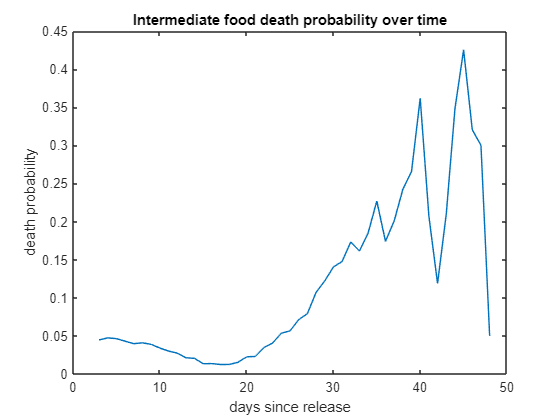

% now plot both the death and settlement probability curves - the only
% reason there are large fluctuations in the death probabilities is that by
% around 40 days, most of the larvae have died anyway, so probabilities
% were gained from fluctuations in small populations hence large variation
figure
plot(midFDeathProb(1, :), midFDeathProb(2, :))
xlabel("days since release")
ylabel("death probability")
title("Intermediate food death probability over time")

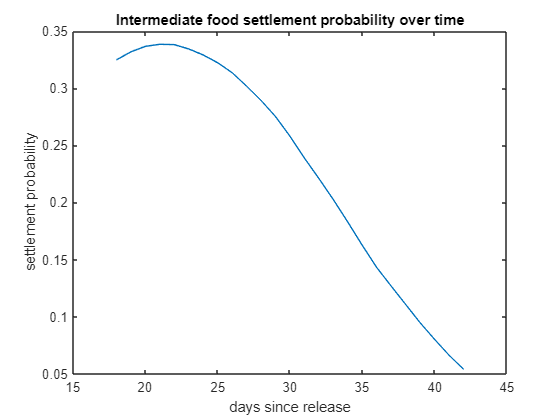

figure
plot(midFSett(1, :), midFSett(2, :))
xlabel("days since release")
ylabel("settlement probability")
title("Intermediate food settlement probability over time")

% can examine the probability of surviving the whole 40 or so days
test = 1 - midFDeathProb(2, :);
test2 = 1;
survivalProp = ones(1, length(midFDeathProb));
survivalProp(1) = test(1);
for i = 2:length(midFDeathProb)
    survivalProp(i) = survivalProp(i-1) * test(i-1);
end

## Assign final reefs and create connectivity matrix

% run the code used to determine the final COTS locations
tic
[finalReefs, status, overReefCount] = assignFinalReefs(COTSStruct, GBRShape, GBRShapeEnlarged, searchCellEnlarged, midFSett, midFDeathProb);
toc

Elapsed time is 24.702336 seconds.


% create the connectivity matrix
connectivityMatrix = createConnectivityMat(initialReefs, finalReefs, GBRShape);

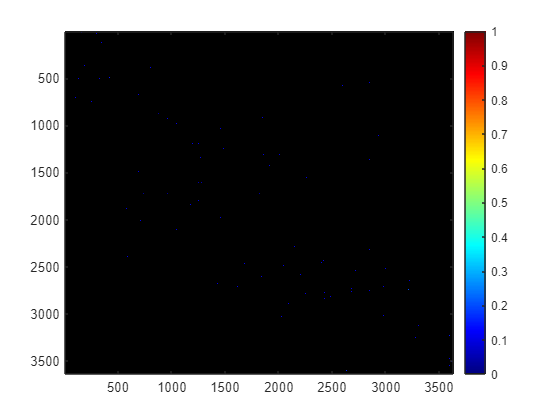

% examine the connectivity matrix
figure
cMap = vertcat([0, 0, 0], jet);
colormap(cMap)
imagesc(connectivityMatrix)
colorbar

% if we want to gain a more interesting connectivity matrix, we may want to
% instead average it over a number of runs
nRuns = 50;
for r = 1:nRuns
    [finalReefs, status, overReefCount] = assignFinalReefs(COTSStruct, GBRShape, GBRShapeEnlarged, searchCellEnlarged, midFSett, midFDeathProb);
    connectivityMatrixCurr = createConnectivityMat(initialReefs, finalReefs, GBRShape);
    if r == 1
        connectivityMatrixMult = connectivityMatrixCurr;
    else
        connectivityMatrixMult = connectivityMatrixMult + connectivityMatrixCurr;
    end
end
connectivityMatrixMult = connectivityMatrixMult / nRuns;

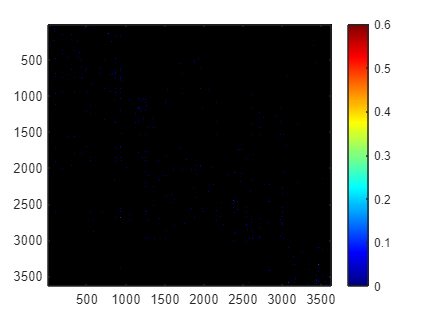

figure
cMap = vertcat([0, 0, 0], jet);
colormap(cMap)
imagesc(connectivityMatrixMult)
colorbar

% let's examine the results stored in the status variable to ensure that
% the death and settlement processes have been carried out correctly
[obsSettProb, obsDeathProb] = convertStatusToProb(status, overReefCount);

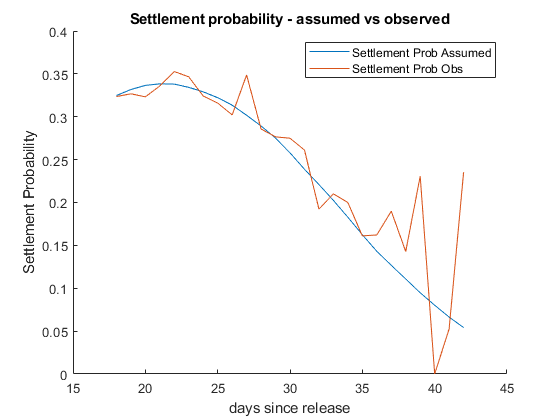

% plot results
figure
hold on
plot(midFSett(1, :), midFSett(2, :))
plot(obsSettProb(1, :), obsSettProb(2, :))
legend("Settlement Prob Assumed", "Settlement Prob Obs")
xlabel("days since release")
ylabel("Settlement Probability")
title("Settlement probability - assumed vs observed")

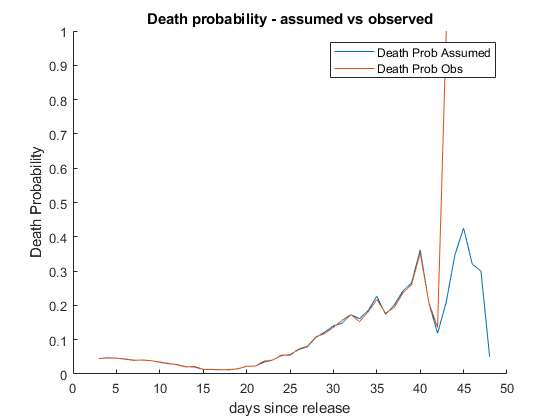


figure
hold on
plot(midFDeathProb(1, :), midFDeathProb(2, :))
plot(obsDeathProb(1, :), obsDeathProb(2, :))
legend("Death Prob Assumed", "Death Prob Obs")
xlabel("days since release")
ylabel("Death Probability")
title("Death probability - assumed vs observed")